# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder and this livescript file. As usual, you should also provide a pdf of the result of running the live script (in the Live Editor, you can **export to pdf** under Save) where all result images should be visible.

Since we need to access the functions and data folder the first step is to add these two locations MATLAB's path.

addpath('./functions');
addpath('./data');

# **Lab 4 - Triangulation**

## **Using RANSAC**

This whole lab is basically concerned with the camera equation


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\lambda u=P\;U$$


For the uncalibrated case, $u$ is a 3-vector with the coordinates of a point in the image (and an added 1)


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;u=\left\lbrack \begin{array}{c}
x\\
y\\
1
\end{array}\right\rbrack$$


and $U$ is a 4-vector containing the coordinates of the corresponding 3D point along with a 1 in its last element. A function

sigma = 0.5;
[Ps, us, U_true] = triangulation_test_case(sigma)

Ps = 1×2 cell array
    {3×4 double}    {3×4 double}


us =  -112.7518  425.2570
    8.2058  230.4404


U_true =     0.8147
    0.9058
    0.1270


is provided for creating a simple test case where you know the correct answer (`U_true`). Gaussian noise of standard deviation `sigma` is added to the image points. Use this example to evaluate your minimal solver.

**Ex 4.1**     Make a minimal solver for the triangulation problem, that is, a function 

U = minimal_triangulation(Ps, us)

U =     0.8163
    0.9067
    0.1347


that takes two camera matrices, `Ps`, and two image points, `us`, and triangulates a 3D point. The image points are a 2 x 2 array whereas the camera matrices is a cell list with one camera matrix in each cell. 

Recall that $\lambda$ is the *depth*. Points with negative depth would lie behind the camera, so negative depths indicate that something is wrong.

**Ex 4.2**     Make a function 

positive = check_depths(Ps, U)

positive =      1     1


positive =      0     0


that takes *N* camera matrices, `Ps`, and a 3D point, `U`, and checks the depth of `U` in each of the cameras. The output should be a an array of boolean values of length *N* that indicates which depths were positive. (Matlab will print boolean values as zeros and ones, so don’t be confused by this.)

**Ex 4.3**     Make a function 

errors = reprojection_errors(Ps, us, U)

errors =     0.3252
    0.4734


that takes *N* camera matrices, `Ps`, *N* image points, `us`, and a 3D point, `U`, and computes a vector with the reprojection errors, that is, the lengths of the reprojection residuals. If a point has negative depth, set the reprojection error to `Inf`. 

**Ex 4.4**     Make a function 

threshold =  2

threshold = 2

[U, nbr_inliers] = ransac_triangulation(Ps, us, threshold) 

U =     0.8163
    0.9067
    0.1347


nbr_inliers = 2

that implements triangulation using RANSAC. Use the number of outliers as loss function. A measurement is deemed as an outlier if the depth is negative or if the reprojection error is larger than `threshold`. 

In `sequence.mat` you find a struct array `triangulation_examples` with triangulation examples. Each example (3D point) has a cell list of camera matrices `Ps` and a 2 x N-array `us` with image points. It will take some time to triangulate all 32183 examples so start with the first 1000 or so. We used a RANSAC threshold of 5 pixels. 

**Ex 4.5**     Make a script `triangulate_sequence` that runs `ransac_triangulation` for all (or at least 1000) of the examples from `sequence.mat`. Store all triangulated points with at least two inliers and plot them using `scatter3`. There will always be a few outliers among the estimated 3D points that make it harder to view the plot. You can use the provided `clean_for_plot.m` to clean it up a bit. 

triangulate_sequence   % Script that you need to create

Uc = clean_for_plot(Us) 

Uc =   -17.4942  -18.2114  -15.7911  -14.1047  -16.7144  -16.4449  -14.9050  -17.9631  -17.2202  -16.6025  -14.5050  -12.7372  -12.6913  -12.5955  -13.0340  -17.6792  -17.8083  -17.5143  -16.9431  -12.6433  -13.0648  -13.1002  -18.3469  -18.1339  -17.2381  -17.1447  -17.0501  -16.9476  -16.9009  -16.7848  -15.6451  -12.6241  -13.0497  -12.9564  -13.1254  -12.9304  -18.3896  -18.2729  -18.0195  -17.8753  -17.5223  -17.5767  -17.3922  -17.3750  -17.4026  -17.4002  -17.2958  -17.1680  -17.1661  -17.1241
    4.1465    4.9835    5.3864    5.7166    5.2835    5.0976    5.5313    5.2585    5.5058    5.5049    5.7114    2.3127    2.5490    2.4171    5.1502    5.2826    5.2881    5.4059    5.3608    3.1106    5.1007    6.1040    5.1432    5.1932    5.6165    5.5625    5.5737    5.5969    5.5518    5.3501    5.4722    3.2917    5.3369    5.2668    5.7314    5.8783    5.0734    5.2692    5.1849    5.5878    5.3629    5.2741    5.4360    5.5060    5.2593    5.2554    5.5985    5.5352    5.5842    

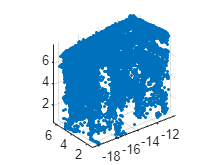

scatter3(Uc(1,:),Uc(2,:),Uc(3,:),'.') 
axis equal

Can you recognize the building? 

**Write your answer with explanation as a comment here.**

% 

## Least squares triangulation 

In this part of the lab you will solve the tringulation problem through least squares. Just as in the case of registration, the following pipeline is recommended: 

    - Use RANSAC to obtain a rough estimate of the parameters (*U*). 

    - Remove all measurements which are outliers with respect to these parameters. 

    - Estimate the least squares parameters using the remaining measurements. 

Note that in this case a *measurement* is a pair consisting of an image point $u_i$ and a camera matrix $P_i$. Don’t forget that points with negative depths should be outliers. 

**Ex 4.6**     Consider a camera matrix 

                        $P_i =\left\lbrack \begin{array}{c}
\longleftarrow a_i^T \longrightarrow \\
\longleftarrow b_i^T \longrightarrow \\
\longleftarrow c_i^T \longrightarrow 
\end{array}\right\rbrack$ ,

a 3D point *U* and an image point $u_i$. Write the formula for the reprojection error $r_i \left(U\right)$ below.

**Your answer here:**


$$r_i \left(U\right)=$$


As you can see, the residuals are no longer linear, so computing a least squares solution will be significantly harder than in the previous lab. In fact, we cannot be sure to find the least squares solution. What we can do is to use local optimization to reduce the sum of squared residuals. We start at the solution produced by Ransac and use a few Gauss-Newton iterations.

**Ex 4.7**     Make a function  

that takes a cell list `Ps` with *N* cameras, a 2 x *N* array `us` of image points and a 3 x 1 array `U`, and computes a 2*N* x 1 array with all the reprojection residuals stacked into a single vector/array. A reprojection residual is a 2D vector corresponding to the difference between the original measurement and the projected point. The stacked vector is the $\bar{r}$ from the lecture notes (page 99).

% usage example
all_residuals = compute_residuals(points3D(1).Ps, points3D(1).xs, Us(:,1))

**Ex 4.8**     Find formulas for the partial derivatives in the Jacobian of $\bar{r}$. The Jacobian should be a 2N x 3- matrix. (Hint: you can start by finding the formula to the Jacobian of the i-th residual, which is a 2x3 matrix.)

## Your answer here:


$$J =\left\lbrack \begin{array}{c}
\\

\end{array}\right\rbrack$$


**Ex 4.9**     Make a function 

that computes the Jacobian given a 3 x 1- vector `U` and a cell array of camera matrices `Ps`. 

% usage example
all_residuals = compute_jacobian(points3D(1).Ps, Us(:,1))

**Ex 4.10**     Use these functions to make a function 

that uses an approximate 3D point `Uhat` as a starting point for Gauss-Newton’s method. Use five GaussNewton iterations. Print the sum of squared residuals after each Gauss-Newton step to verify that it decreases. 

% usage example
Uref = refine_triangulation(points3D(1).Ps, points3D(1).xs, Us(:,1))

**Ex 4.11**     Try your `refine_triangulation` on the data in `gauss_newton.ma`t. First we will plot the points given in `Uhat`, then refine each point using your function and plot the results using `scatter3`. You should see an improvement. 

% don't forget to plot your results
load gauss_newton
scatter3(Uhat(1,:),Uhat(2,:),Uhat(3,:),'.') 
axis equal

Ps = {P,P_tilde};

N = size(Uhat,2);
Uref = zeros(3,N);
for i = 1:N
    Uref(:,i) = refine_triangulation(Ps, [u(:,i), u_tilde(:,i)], Uhat(:,1));
end
scatter3(Uref(1,:),Uref(2,:),Uref(3,:),'.') 
axis equal

**Ex* 4.12**     Compute the camera positions for the data in `gauss_newton.mat` and plot them together with the estimated 3D points. Try to understand why the noise in the estimated points looks as it does. 

% YOUR CODE HERE; don't forget to plot your results



For the next exercise try the following way to match features, 

The approximate option makes it go significantly faster. A Lowe ratio of 0.9 is very high, but it makes the model more *dens*e. 

**Ex 4.13**     There are images `duomo.jpg` and `duomo_tilde.jpg` in the lab folder and also a data file `duomo.mat` with two camera matrices. Extract SIFT features from the two images using `detectSIFTFeatures` and `extractFeatures`, then match them using `matchFeatures`. Also store the color of each SIFT point. It doesn’t matter from which of the images you select the color information. 

Use your triangulation code (don’t forget r`efine_triangulation`) to triangulate the points and plot them with the right color using `scatter3`. Again, you can use `clean_for_plot.m` to remove outliers among the estimated 3D points. Beware that triangulating all the points will take a little time so work with a subset until you are sure that the code works. 

%Your code here
load duomo



## **Essential Matrix**

The two exercises below are optional and therefore marked with *****.

**Ex* 4.14**     Load the data in `P.mat`. There you will find two calibrated camera matrices, `P1` and `P2`. Make a function 

that computes the essential matrix `E` from `P1` and `P2` .

load P.mat


**Ex* 4.15**     Similar to the reprojection error in the triangulation problem, the essential matrix can also be used for outlier detection using the residual


$$r^2 =\frac{\left|{\tilde{x} }^T \;E\;x\;\right|}{{\left\|S\;E\;x\right\|}^2 +{\left\|S\;E^T \;\;\tilde{x} \right\|}^2 \;},\;\;\;\;\;\;\;\;\;\;S=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


where $x$ and $\tilde{x}$ are the image projections of a 3D point *X* using some arbitrary camera matrices $P$ and $\tilde{P}$, respectively. Note that $r$ does not depend on X. Assuming that you are using a similar threshold for outlier detection, for a set of pixel correspondences, you would get `I1` inliers if you use the residual from the triangulation problem and `I2` inliers if you used the residual from (4.4). Which one is greater, `I1` or `I2`? Why? 